# Mauna Loa Carbon Dioxide Concentrations

The Excel spreadsheet CO2 Mauna Loa.xlsx contains the CO2 data from Hawaii provided by the [Earth System Research Laboratory](https://www.esrl.noaa.gov/) of the National Oceanic and Atmospheric Administration (NOAA).

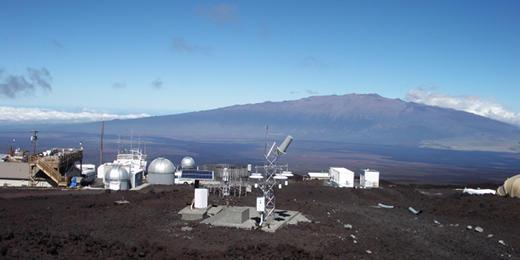

### Let's read the data in and plot it:

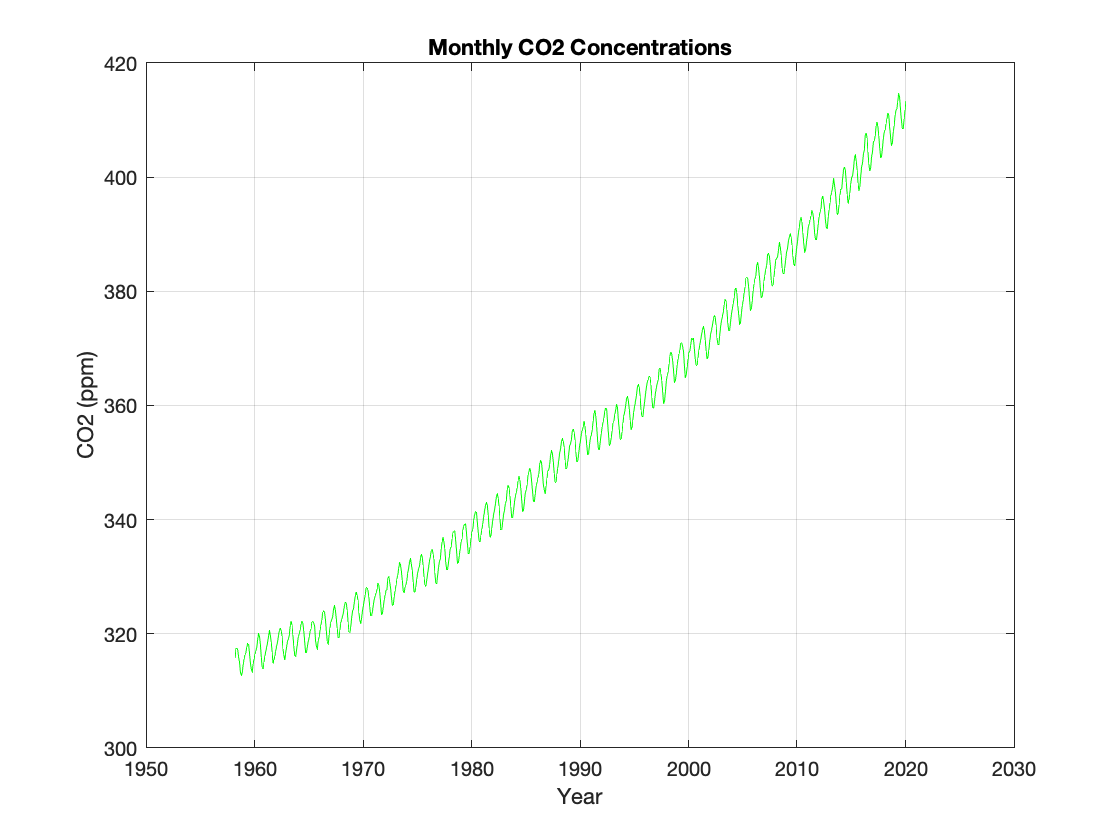

co2 = xlsread("CO2 Mauna Loa.xlsx");
year = co2(:,3);
CO2 = co2(:,4); 
plot(year,CO2,'g'); grid on;
title("Monthly CO2 Concentrations");
xlabel("Year"); ylabel("CO2 (ppm)"); 

### Smooth the data and plot it with the original data:

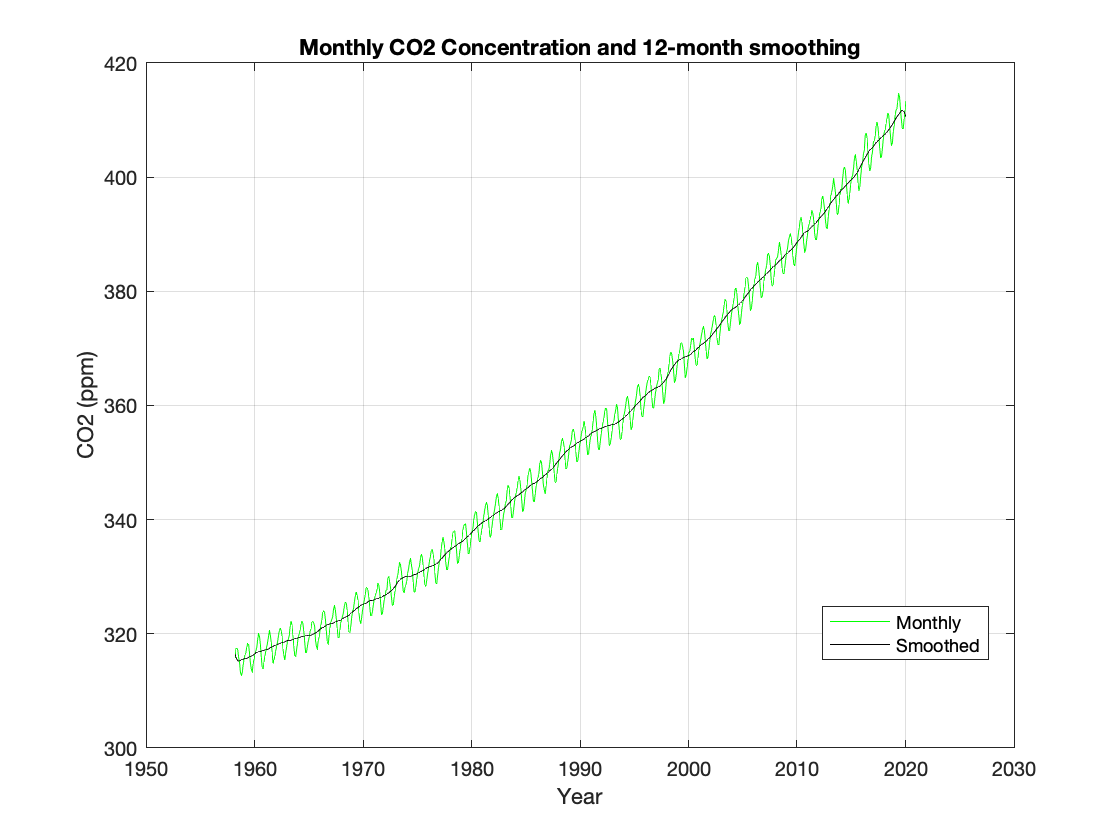

window = 12;
smoothed = smoothdata(CO2,'movmean',window);
plot(year,CO2,'g',year,smoothed,'k'); grid on;
title(sprintf('Monthly CO2 Concentration and %d-month smoothing',window));
xlabel("Year"); ylabel("CO2 (ppm)");
legend('Monthly','Smoothed','location','best');

### Model the growth of CO2 as exponential and compare to smoothed data:

#### 
$${\textrm{CO}}_2 =\mathit{\mathbf{a}}+\mathit{\mathbf{b}}{\mathit{\mathbf{e}}}^{\mathit{\mathbf{n}}\left(\textrm{year}-1958\right)}$$


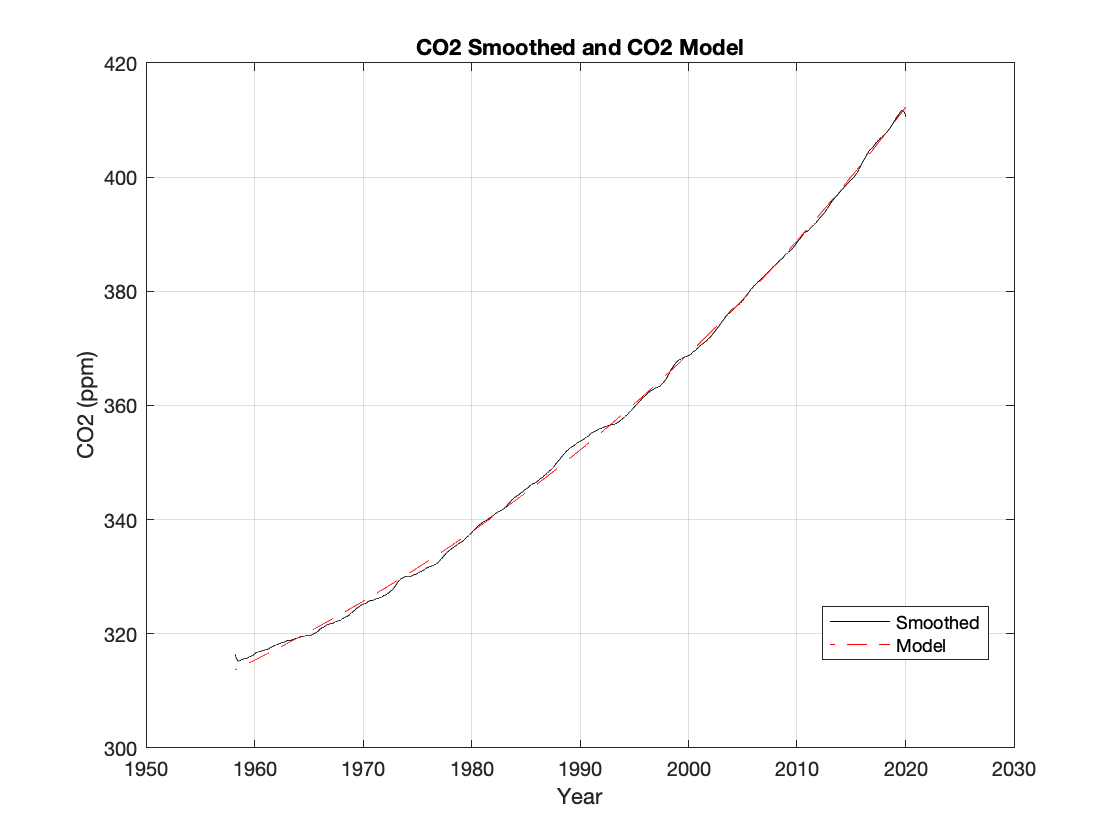

model = fittype('a+b*exp(n*(year-1958))','independent','year');
options = fitoptions('Method','NonlinearLeastSquares','StartPoint',[0,0,0]);
CO2_fit = fit(year,CO2,model,options);
CO2_model = CO2_fit.a + CO2_fit.b*exp(CO2_fit.n*(year-1958));
plot(year,smoothed,'k',year,CO2_model,'r--'); grid on;
title("CO2 Smoothed and CO2 Model");
xlabel("Year"); ylabel("CO2 (ppm)"); 
legend('Smoothed','Model','location','best');

### Extend exponential model from end of monthly data to future:

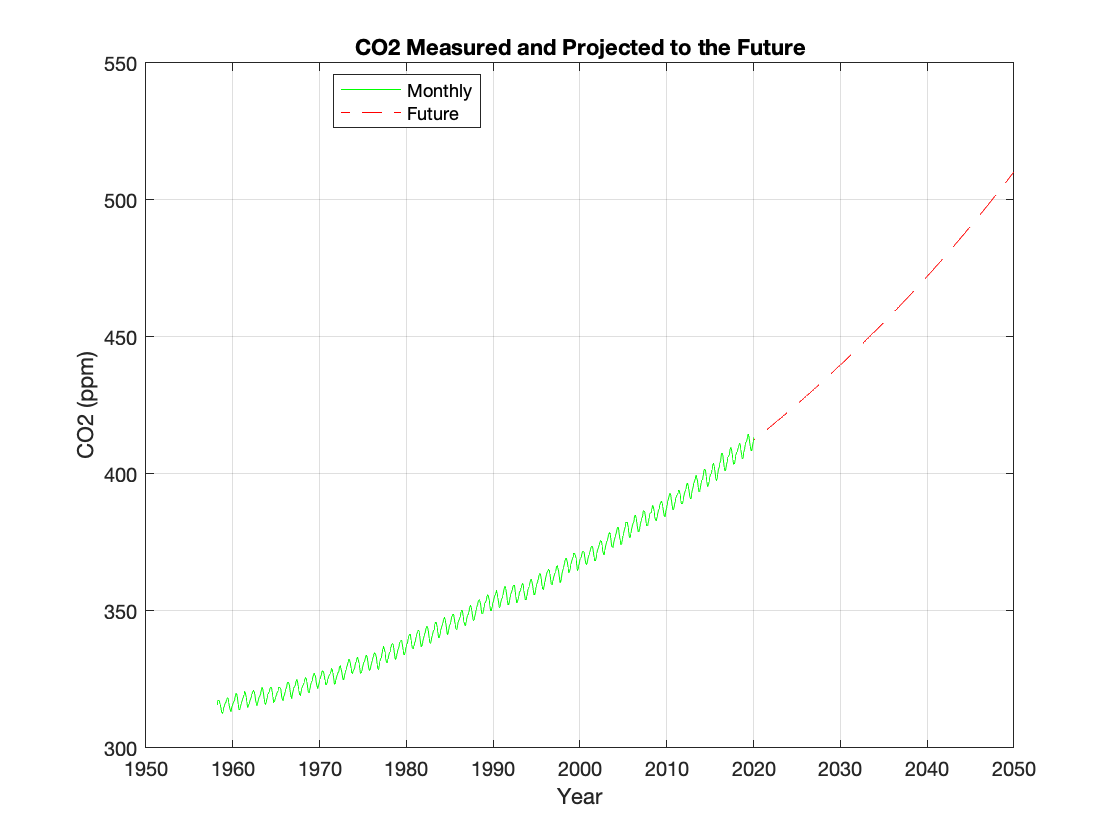

future= year(end):1/12:2050;
CO2_future = CO2_fit.a + CO2_fit.b*exp(CO2_fit.n*(future-1958));
plot(year,CO2,'g',future,CO2_future,'r--'); grid on;
title("CO2 Measured and Projected to the Future");
xlabel('Year'); ylabel("CO2 (ppm)");
legend('Monthly',"Future",'location','best');

fprintf('The predicted CO2 concentration for January %.0f is %0.f ppm.',...
    ceil(future(end)),CO2_future(end));

The predicted CO2 concentration for January 2050 is 510 ppm.